## Assignment 5 (GE22M019)

Discretized state-space model of a system is represented below.

Am = [2 0; 6 1]

Bm = [-1; -3]

Cm = [0 -1]

Dm = [0]

x0 (initial states) = [0 0]

The closed loop poles for the initial values of the discretized system 

Control move penalty:  5,  Prediction horizon: 4,  Control horizon: 1 are 0.0017,0.8845 ± 0.1957i

The set point of the system is 1.5.

% Discrete model input parameters
clear
Am = [2 0; 6 1]; 
Bm = [-1; -3];  
Cm = [0 -1]; 
Dm = [0];
% Initial State
xm=[0;0];  
N_sim = 100;
r=1.5*ones(N_sim,1);
u=0;                % All previous u are zero
y=0;

% Initial parameters to verify eigenvalues
Np = 4;     % Prediction Horizon
Nc = 1;     % Control Horizon
R = 5;      % Control move penalty or input weight

% % Parameters to tune for optimality
% Np = 20;    % Prediction Horizon
% Nc = 4;     % Control Horizon
% R = 1;   % Control move penalty or input weight

%% Create augmented model for MPC design using input parameters
% Code refered from MPC Design and Implementation - Wang
[m1,n1]=size(Cm);
[n1,n_in]=size(Bm);
A=eye(n1+m1,n1+m1);
A(1:n1,1:n1)=Am;
A(n1+1:n1+m1,1:n1)=Cm*Am;
B=zeros(n1+m1,n_in);
B(1:n1,:)=Bm;
B(n1+1:n1+m1,:)=Cm*Bm;
C=zeros(m1,n1+m1);
C(:,n1+1:n1+m1)=eye(m1,m1);

% Find the quantities required for optimal control move
n=n1+m1;
Xf=zeros(n,1); % initial state feedback variable
h(1,:)=C;
F(1,:)=C*A;
for kk=2:Np
h(kk,:)=h(kk-1,:)*A;
F(kk,:)= F(kk-1,:)*A;
end
v=h*B;
Phi=zeros(Np,Nc);   % declare the dimension of Phi
Phi(:,1)=v;         % first column of Phi
for i=2:Nc
Phi(:,i)=[zeros(i-1,1);v(1:Np-i+1,1)]; %Toeplitz matrix
end
BarRs=ones(Np,1);
Phi_Phi= Phi'*Phi;
Phi_F= Phi'*F;
Phi_R=Phi'*BarRs;

[n,x]=size(B);
Xf=zeros(n,1);      % initial state feedback variable

% Optimal control move calculation
for kk=1:N_sim
DeltaU=inv(Phi_Phi+R*eye(Nc,Nc))*(Phi_R*r(kk)-Phi_F*Xf);
deltau=DeltaU(1,1);
deltau_values(kk) = deltau;
u=u+deltau;
u1(kk)=u;
y1(kk)=y;
xm_old=xm;
xm=Am*xm+Bm*u;
y=Cm*xm;
Xf=[xm-xm_old;y];
end

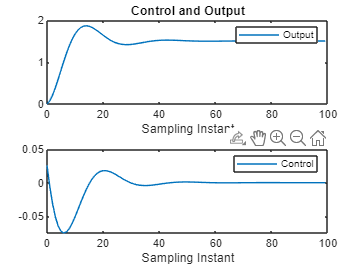

% Plot the Control Move and corresponding Output
k=0:(N_sim-1);
figure
subplot(211)
plot(k,y1)
title("Control and Output")
xlabel('Sampling Instant')
legend('Output')
subplot(212)
plot(k,u1)
xlabel('Sampling Instant')
legend('Control')

% Closed loop poles calculation
Kmpc = inv((Phi_Phi+R*eye(Nc,Nc)))*Phi_F;
kmpc = Kmpc(1,:);
cloop_poles = eig(A-B*kmpc)

cloop_poles =    0.0017 + 0.0000i
   0.8845 + 0.1957i
   0.8845 - 0.1957i


disp("The closed loop radius is:")

The closed loop radius is:


cloop_poles_radius = abs(cloop_poles)

cloop_poles_radius =     0.0017
    0.9058
    0.9058


% Calculate the control energy: delU*R*delU'
control_energy = (deltau_values)*R*deltau_values'

control_energy = 0.0188

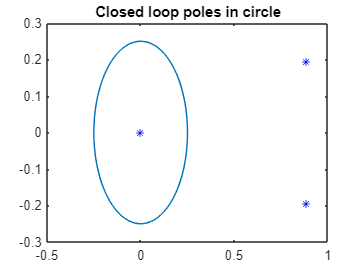

% Initial poles plotted in circle
figure;
t = linspace(0,2*pi,100);
x = 0.25*cos(t);
y = 0.25*sin(t);
plot(x,y)

hold on
plot(real(cloop_poles),imag(cloop_poles),'b*')
title("Closed loop poles in circle")